close all
clearvars
clc
warning('off','all')

%path ='C:\Users\adria\Documents\Uni\LM II anno\Tesi\opti_data.xlsx';
path ='C:/A_Tesi/Python/CTM-s/opti_data.xls';
disp = 1;
%% extract data
T = readtable(path);
A = table2array(T);
cell_in = A(:, 1);
cell_out = A(:, 2);
delta = A(:, 3);
integral = A(:, 4);
max_delta = A(:,5);
pi_greco = A(:, 6);
fit_name=["poly11","poly12","poly21","poly22","poly13","poly31","poly23","poly32","poly33", ...
          "poly14","poly41","poly24","poly42","poly34","poly43","poly44",...
          "poly15","poly51","poly25","poly52","poly35","poly53","poly45","poly54","poly55"];

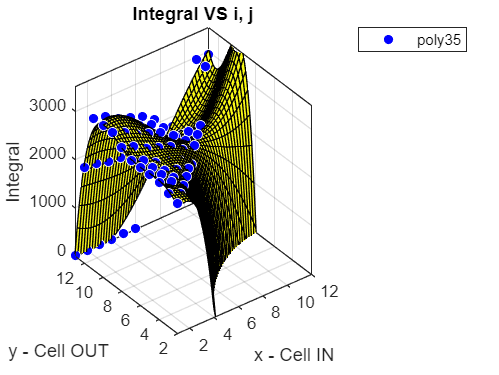

%% Integral with fifferent i, j and delta fixed
delta = 360;
x = [];
y = [];
z = [];
for i=1:length(A(:,1))
    if(A(i,3)==delta)
        x=[x A(i,1)];
        y=[y A(i,2)];
        z=[z A(i,4)];
    end
end
x=x'; 
y=y'; 
z=z';

[f, gof] = fit([x, y],z,fit_name(1));
f_best=f;
gof_best=gof;
round_adjrsq = round(gof_best.adjrsquare,2);
for i=2:length(fit_name)
    [f, gof] = fit([x, y],z,fit_name(i));
    if(round(gof.adjrsquare,2) > round_adjrsq)
        f_best=f;
        gof_best=gof;
        round_adjrsq = round(gof_best.adjrsquare,2);
    end
end

if(disp>0)
    figure()
    plot(f_best,[x y],z)
    zlim([0 3500]);
    xlabel('x - Cell IN')
    ylabel('y - Cell OUT')
    zlabel("Integral")
    title("Integral VS i, j")
    legend(type(f_best))
    grid on
end

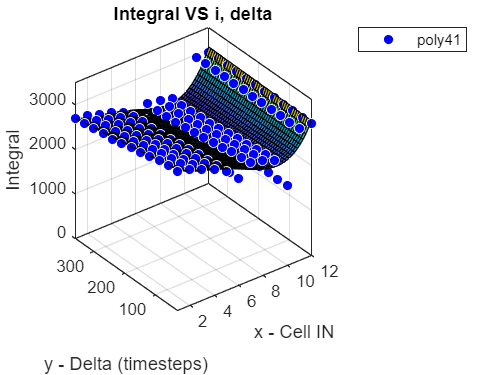

%% Integral with different i, delta(5-60 min) and j fixed
j = 1;
x = [];
y = [];
z = [];
for i=1:length(A(:,1))
    if(A(i,2)==A(i,1)+j)
        x=[x A(i,1)];
        y=[y A(i,3)];
        z=[z A(i,4)];
    end
end
x=x'; 
y=y'; 
z=z';

[f, gof] = fit([x, y],z,fit_name(1));
f_best=f;
gof_best=gof;
round_adjrsq = round(gof_best.adjrsquare,2);
for i=2:length(fit_name)
    [f, gof] = fit([x, y],z,fit_name(i));
    a = round(gof.adjrsquare,2);
    if(a > round_adjrsq)
        f_best=f;
        gof_best=gof;
        round_adjrsq = round(gof_best.adjrsquare,2);
    end
end

if(disp>0)
    figure()
    plot(f_best,[x y],z)
    zlim([0 3500]);
    xlabel('x - Cell IN')
    ylabel('y - Delta (timesteps)')
    zlabel("Integral")
    title("Integral VS i, delta")
    legend(type(f_best))
    grid on
end

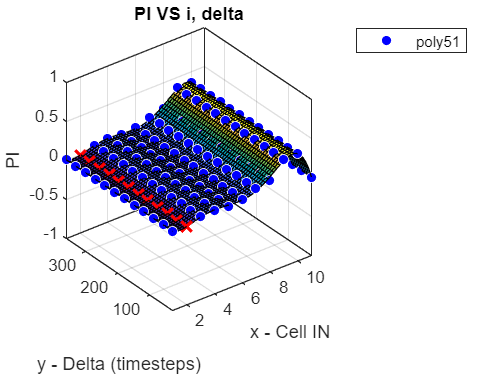

%% Pi with different i, delta(5-60 min) and j fixed
j = 2;
x = [];
y = [];
z = [];
for i=1:length(A(:,1))
    if(A(i,2)==A(i,1)+j)
        x=[x A(i,1)];
        y=[y A(i,3)];
        z=[z A(i,6)];
    end
end
x=x'; 
y=y'; 
z=z';

[f, gof] = fit([x, y],z,fit_name(1));
f_best=f;
gof_best=gof;
round_adjrsq = round(gof_best.adjrsquare,2);
for i=2:length(fit_name)
    [f, gof] = fit([x, y],z,fit_name(i));
    a = round(gof.adjrsquare,2);
    if(a > round_adjrsq)
        f_best=f;
        gof_best=gof;
        round_adjrsq = round(gof_best.adjrsquare,2);
    end
end

if(disp>0)
    figure()
    plot(f_best,[x y],z, 'Exclude', z < 0)
    zlim([-1 1]);
    xlabel('x - Cell IN')
    ylabel('y - Delta (timesteps)')
    zlabel("PI")
    title("PI VS i, delta")
    legend(type(f_best))
    grid on
end